## Reproducción de ejemplo de taller

%1. Creacion de puntos de circulo
N = 100;
X1 = [linspace(-1,1,N)]'; %crear puntos equidistantes
Y1 = sqrt(1-X1.^2); %circulo

X2 = [linspace(1,-1,N)]';
Y2 = -sqrt(1-X2.^2);
X = [X1;X2];
Y = [Y1;Y2];
Z = X+1j*Y;

% Introduccion de ruido
sd = 0.5;
rX = normrnd(0,sd,[length(X),1]); %ruido para parte real
rY = normrnd(0,sd,[length(X),1]); % ruido para la parte imaginaria
Xr = X+rX;
Yr = Y+rY;
Zr = Xr + 1j*Yr;

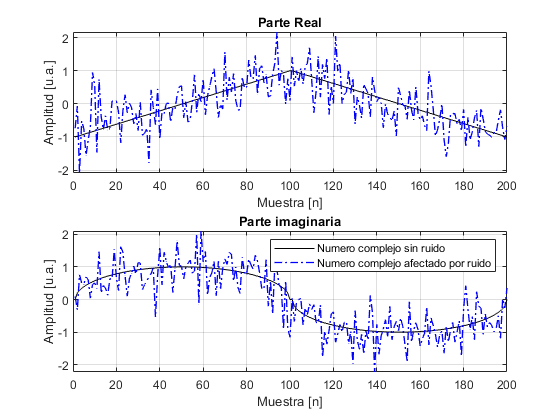

%% Grafica de ruido para parte real e imaginaria
figure,
subplot(2,1,1);
plot(X,"k");
hold on;
plot(Xr,"-.b","LineWidth",1);
xlabel("Muestra [n]");
ylabel("Amplitud [u.a.]");
title("Parte Real");
grid on;

subplot(2,1,2);
plot(Y,"k");
xlabel("Muestra [n]");
ylabel("Amplitud [u.a.]");
hold on;
plot(Yr,"-.b","LineWidth",1);
title("Parte imaginaria");
legend("Numero complejo sin ruido", "Numero complejo afectado por ruido");
grid on;

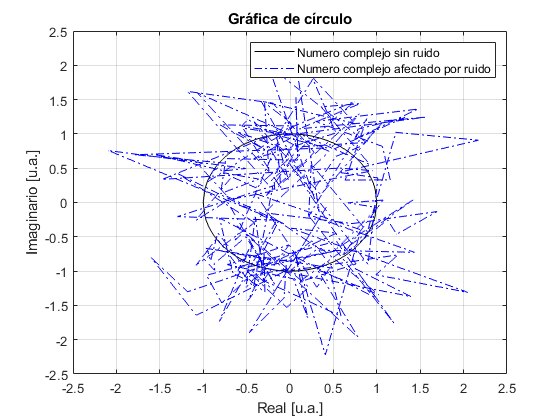

%% Grafica de circulo con y sin ruido
figure, plot(Z,"k");
grid on;
hold on;
plot(Zr,"-.b");
xlabel("Real [u.a.]");
ylabel("Imaginario [u.a.]");
legend("Numero complejo sin ruido", "Numero complejo afectado por ruido");
title("Gráfica de círculo");

%% Obtencion de los coeficientes de Fourier
freqs = fft(Z);
freqs_r = fft(Zr);

## Graficas de amplitud y angulo de los coeficientes

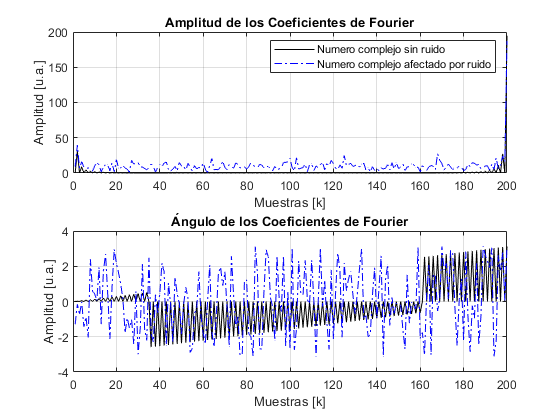

figure,
subplot(2,1,1);
plot(abs(freqs),'k');
grid on;
hold on;
plot(abs(freqs_r),"-.b");
xlabel("Muestras [k]");
ylabel("Amplitud [u.a.]")
title("Amplitud de los Coeficientes de Fourier");
legend("Numero complejo sin ruido","Numero complejo afectado por ruido");

subplot(2,1,2);
plot(angle(freqs),'k');
xlabel("Muestras [k]");
ylabel("Amplitud [u.a.]")
grid on;
hold on;
plot(angle(freqs_r),"-.b");
title("Ángulo de los Coeficientes de Fourier")

%% Filtrado y reconstruccion
% indices de frecuencias que se van a igualar a 0
mitad = round(length(freqs/2));
zero_sample_idx = [20:181]; % debe ser simetrico con respecto a mitad
freqs_rem = freqs_r;
freqs_rem(zero_sample_idx) = 0;

% indices de frqcuencias seleccionados personalmente
zero_sample_idx_2 = [5:196]; % debe ser simetrico con respecto a mitad
freqs_rem_2 = freqs_r;
freqs_rem_2(zero_sample_idx_2) = 0;

% Reconstruccion de la señal y el circulo
Z_rec = ifft(freqs_rem);
Z_rec_2 = ifft(freqs_rem_2);

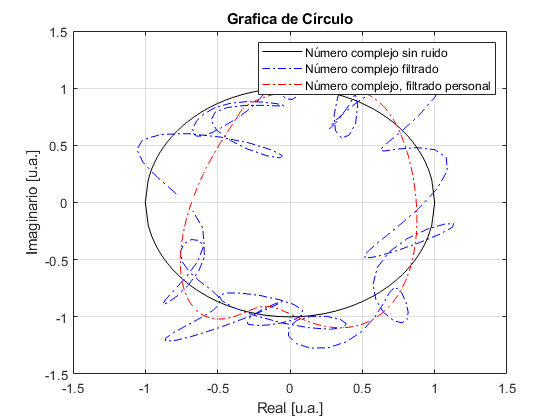

%% Graficas de señal, señal con ruido y señal reconstruida
% Con ejemplo de taller
figure
plot(Z,'k');
hold on;
grid on;
plot(Z_rec,'-.b');
hold on;
plot(Z_rec_2,"-.r");
xlabel("Real [u.a.]");
ylabel("Imaginario [u.a.]");
title("Grafica de Círculo");
legend("Número complejo sin ruido","Número complejo filtrado","Número complejo, filtrado personal");

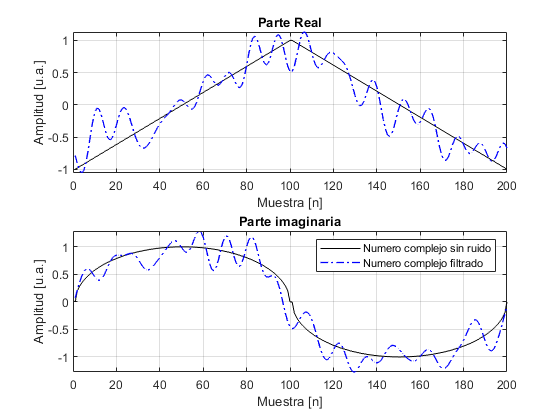

%% Graficas de parte real y parte imaginaria reconstruidas
figure
subplot(2,1,1);
plot(X,"k");
hold on;
plot(real(Z_rec),"-.b","LineWidth",1);
xlabel("Muestra [n]");
ylabel("Amplitud [u.a.]");
title("Parte Real");
grid on;

subplot(2,1,2);
plot(Y,"k");
xlabel("Muestra [n]");
ylabel("Amplitud [u.a.]");
hold on;
plot(imag(Z_rec),"-.b","LineWidth",1);
title("Parte imaginaria");
legend("Numero complejo sin ruido", "Numero complejo filtrado");
grid on;

## Ejemplo 1: Corazón

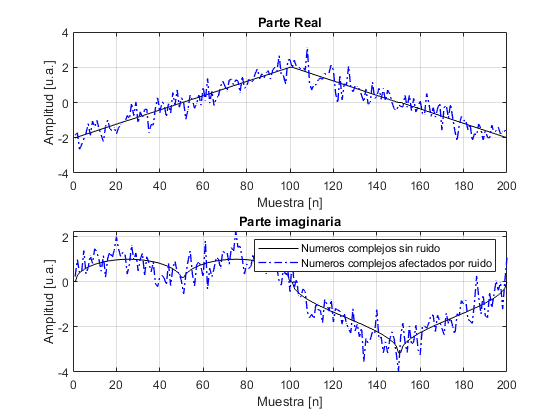

Zcor = f_corazon();
Zcor_r = f_add_noise(Zcor,0.5);
leg = ["Numeros complejos sin ruido","Numeros complejos afectados por ruido"];
colors = ["k","b"];
% Grafica de parte real e imaginaria con/sin ruido
f_real_imag_plots(Zcor,Zcor_r,leg);

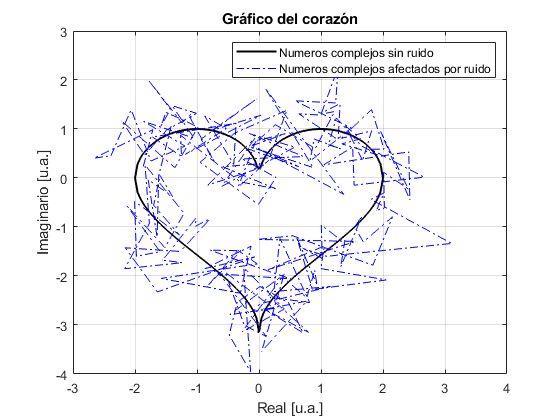

% Grafica de señal original y señal con ruido
f_plot_in_plane([Zcor, Zcor_r],leg,colors, "Gráfico del corazón")

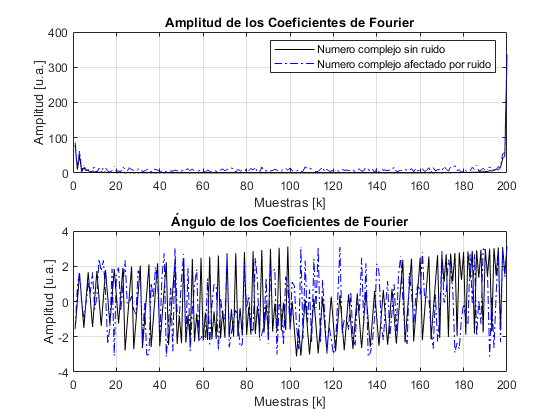

% Grafica de magnitud y angulo de frecuencias
Zcor_w = fft(Zcor);
Zcor_w_r = fft(Zcor_r);
f_plot_ang_phase(Zcor_w, Zcor_w_r)

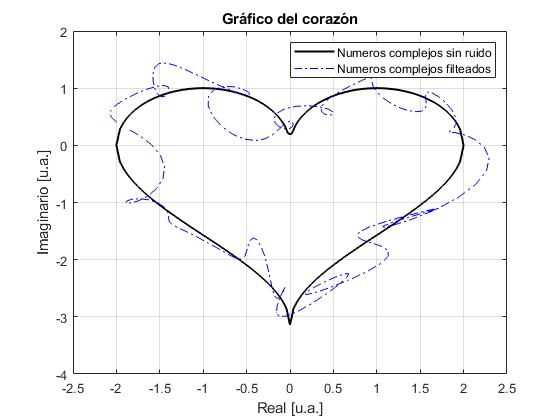

% Eliminacion de frecuencias altas
zero_sample_idx = [20:181]; % debe ser simetrico con respecto a mitad
Zcor_w_r_rem = Zcor_w_r;
Zcor_w_r_rem(zero_sample_idx) = 0;

% Reconstruccion de señal
Zcor_rec = ifft(Zcor_w_r_rem);

% Graficas de señal reconstruida
leg_rec = ["Numeros complejos sin ruido","Numeros complejos filteados"];
colors = ["k","b"];

f_plot_in_plane([Zcor, Zcor_rec],leg_rec,colors, "Gráfico del corazón") % en plano complejo

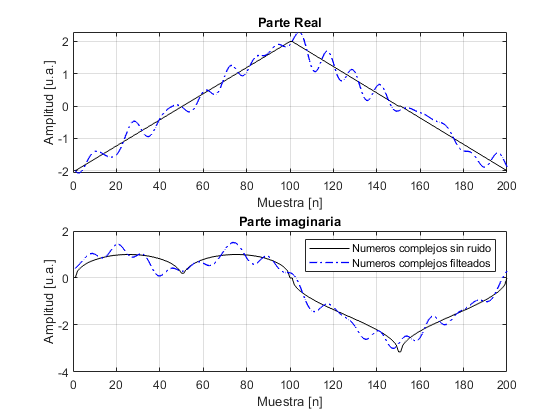

f_real_imag_plots(Zcor,Zcor_rec,leg_rec) % parte real e imaginaria

## Ejemplo 2: Pentágono

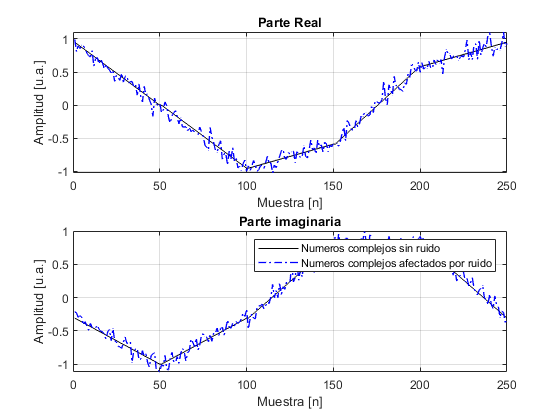

Zpol = f_poligono(5);
Zpol_r = f_add_noise(Zpol,0.08);
leg = ["Numeros complejos sin ruido","Numeros complejos afectados por ruido"];
colors = ["k","b"];
% Grafica de parte real e imaginaria con/sin ruido
f_real_imag_plots(Zpol,Zpol_r,leg);

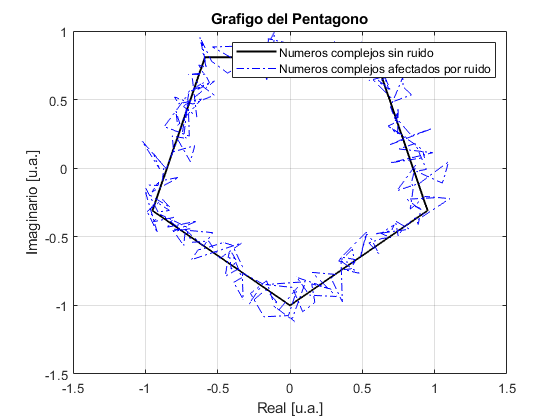

% Grafica de señal original y señal con ruido
f_plot_in_plane([Zpol, Zpol_r],leg,colors, "Grafigo del Pentagono")

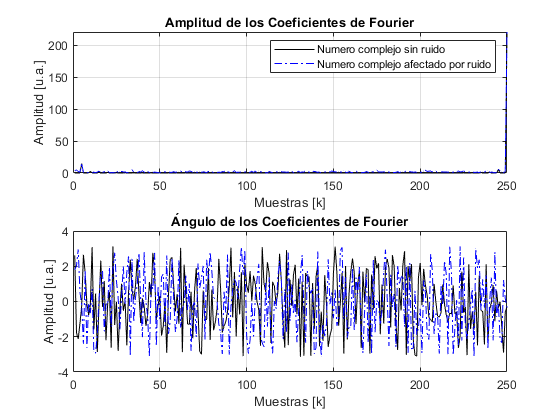


% Grafica de magnitud y angulo de frecuencias
Zpol_w = fft(Zpol);
Zpol_w_r = fft(Zpol_r);
f_plot_ang_phase(Zpol_w, Zpol_w_r);

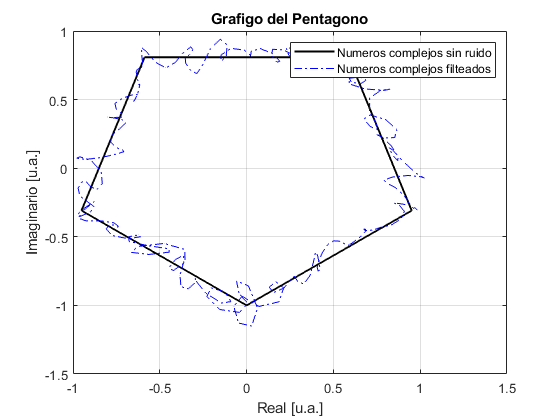


% Eliminacion de frecuencias altas
mitad = round(length(Zpol)/2);
N = 70; % indices para quitar antes y despues de la mitad centrado en la mitad
zero_sample_idx = [mitad - N:mitad+N+1]; % debe ser simetrico con respecto a mitad
if zero_sample_idx(1) <= 0 | zero_sample_idx(end) > length(Zpol)
    disp("ERROR: extremos de arreglo de indices que se quitan son suyperiores a limite ")
end

Zpol_w_r_rem = Zpol_w_r;
Zpol_w_r_rem(zero_sample_idx) = 0;

% Reconstruccion de señal
Zpol_rec = ifft(Zpol_w_r_rem);

% Graficas de señal reconstruida
leg_rec = ["Numeros complejos sin ruido","Numeros complejos filteados"];
colors = ["k","b"];

f_plot_in_plane([Zpol, Zpol_rec],leg_rec,colors, "Grafigo del Pentagono") % en plano complejo

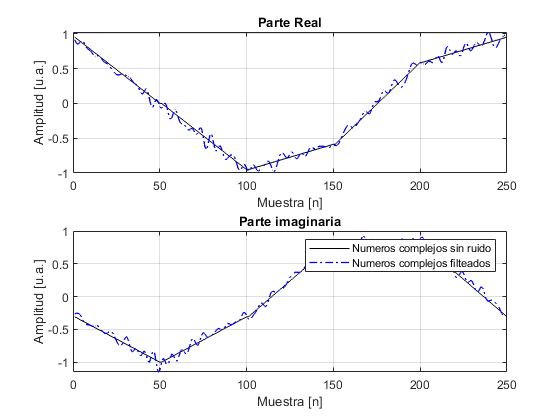

f_real_imag_plots(Zpol,Zpol_rec,leg_rec) % parte real e imaginaria

## Ejemplo 3: Triángulo

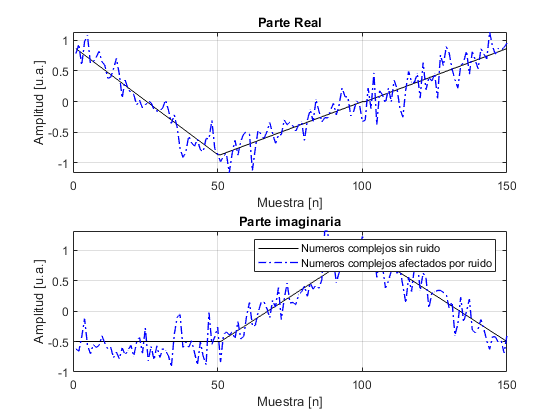

Zpol2 = f_poligono(3);
Zpol2_r = f_add_noise(Zpol2,0.2);
leg = ["Numeros complejos sin ruido","Numeros complejos afectados por ruido"];
colors = ["k","b"];
% Grafica de parte real e imaginaria con/sin ruido
f_real_imag_plots(Zpol2,Zpol2_r,leg);

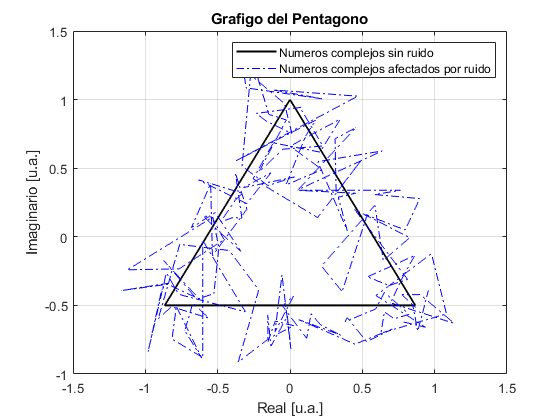

% Grafica de señal original y señal con ruido
f_plot_in_plane([Zpol2, Zpol2_r],leg,colors, "Grafigo del Pentagono")

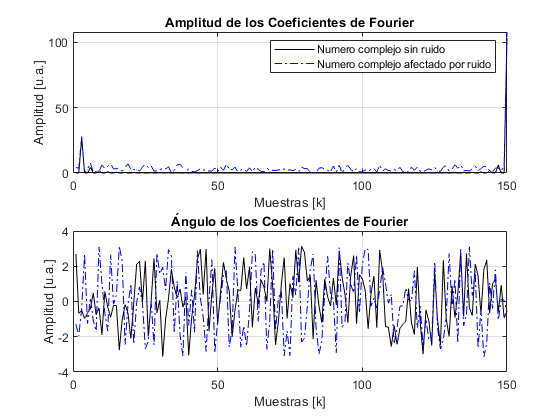

% Grafica de magnitud y angulo de frecuencias
Zpol2_w = fft(Zpol2);
Zpol2_w_r = fft(Zpol2_r);
f_plot_ang_phase(Zpol2_w, Zpol2_w_r);

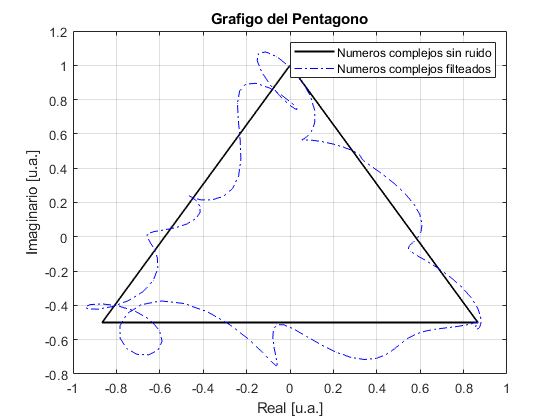

% Eliminacion de frecuencias altas
mitad = round(length(Zpol2)/2);
N = 60; % indices para quitar antes y despues de la mitad centrado en la mitad
zero_sample_idx = [mitad - N:mitad+N+1]; % debe ser simetrico con respecto a mitad
if zero_sample_idx(1) <= 0 | zero_sample_idx(end) > length(Zpol2)
    disp("ERROR: extremos de arreglo de indices que se quitan son suyperiores a limite ")
end
Zpol2_w_r_rem = Zpol2_w_r;
Zpol2_w_r_rem(zero_sample_idx) = 0;

% Reconstruccion de señal
Zpol2_rec = ifft(Zpol2_w_r_rem);

% Graficas de señal reconstruida
leg_rec = ["Numeros complejos sin ruido","Numeros complejos filteados"];
colors = ["k","b"];

f_plot_in_plane([Zpol2, Zpol2_rec],leg_rec,colors, "Grafigo del Pentagono") % en plano complejo

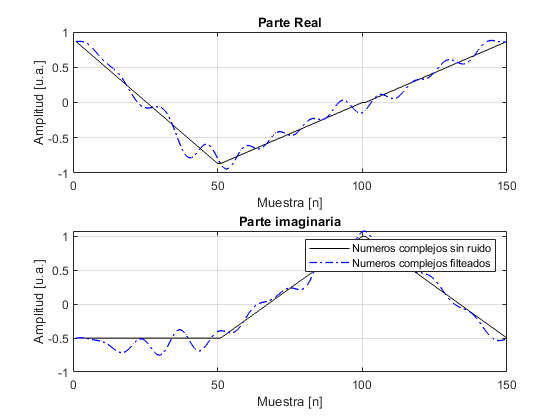

f_real_imag_plots(Zpol2,Zpol2_rec,leg_rec) % parte real e imaginaria

## Ejemplo 4: estrella

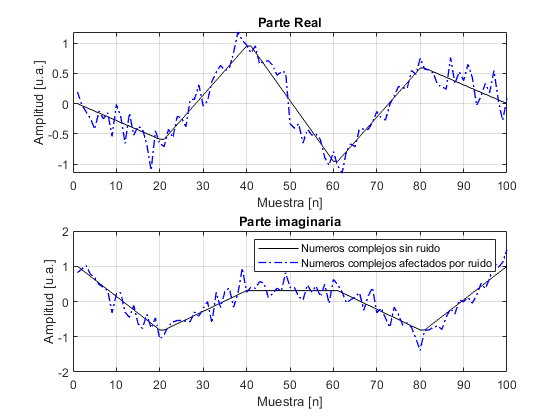

Z_est = f_estrella();
Z_est_r = f_add_noise(Z_est,0.2);
leg = ["Numeros complejos sin ruido","Numeros complejos afectados por ruido"];
colors = ["k","b"];
% Grafica de parte real e imaginaria con/sin ruido
f_real_imag_plots(Z_est,Z_est_r,leg);

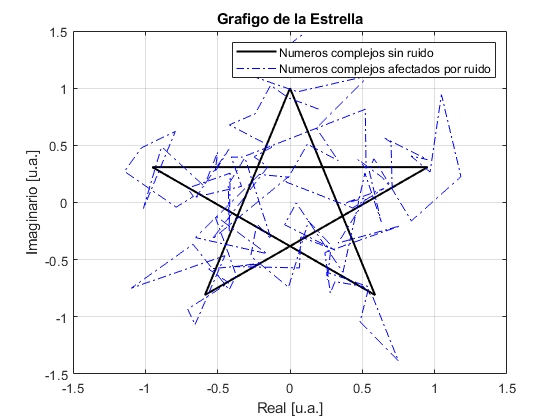

% Grafica de señal original y señal con ruido
f_plot_in_plane([Z_est, Z_est_r],leg,colors, "Grafigo de la Estrella")

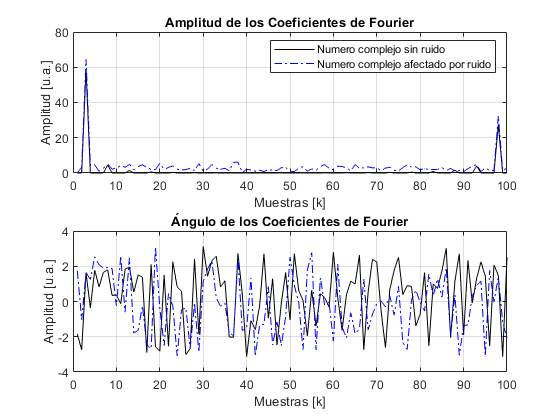

% Grafica de magnitud y angulo de frecuencias
Z_est_w = fft(Z_est);
Z_est_w_r = fft(Z_est_r);
f_plot_ang_phase(Z_est_w, Z_est_w_r);

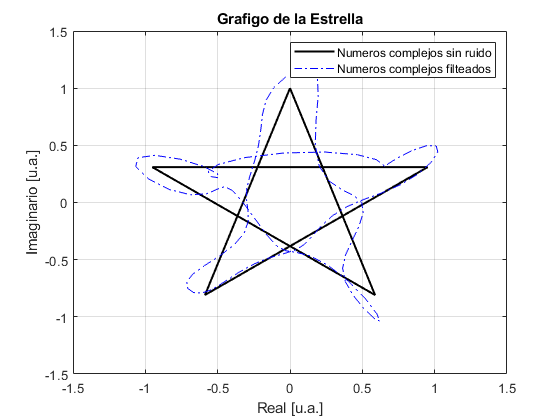

% Eliminacion de frecuencias altas
mitad = round(length(Z_est)/2);
N = 35; % indices para quitar antes y despues de la mitad centrado en la mitad
zero_sample_idx = [mitad - N:mitad+N+1]; % debe ser simetrico con respecto a mitad
if zero_sample_idx(1) <= 0 | zero_sample_idx(end) > length(Zpol2)
    disp("ERROR: extremos de arreglo de indices que se quitan son suyperiores a limite ")
end
Z_est_w_r_rem = Z_est_w_r;
Z_est_w_r_rem(zero_sample_idx) = 0;

% Reconstruccion de señal
Z_est_rec = ifft(Z_est_w_r_rem);

% Graficas de señal reconstruida
leg_rec = ["Numeros complejos sin ruido","Numeros complejos filteados"];
colors = ["k","b"];

f_plot_in_plane([Z_est, Z_est_rec],leg_rec,colors, "Grafigo de la Estrella") % en plano complejo

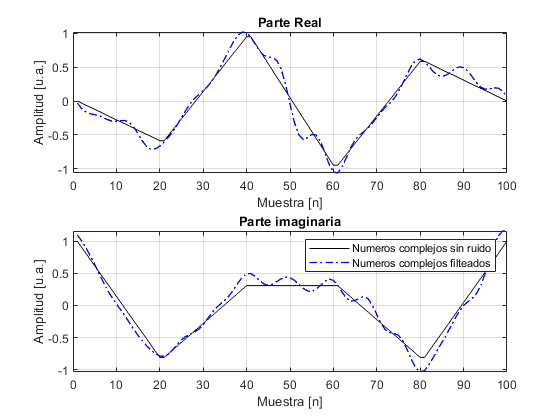

f_real_imag_plots(Z_est,Z_est_rec,leg_rec) % parte real e imaginaria

## Ejemplo 5: Cuadrado

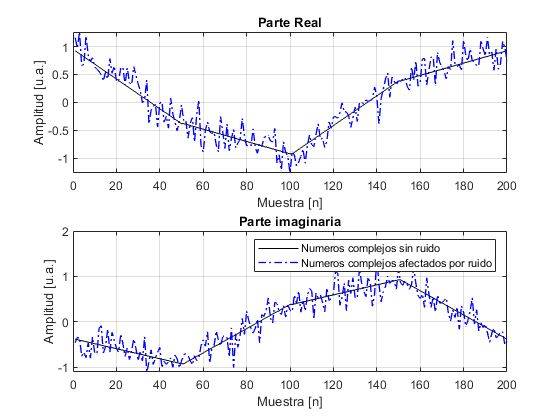

Zpol3 = f_poligono(4);
Zpol3_r = f_add_noise(Zpol3,0.2);
leg = ["Numeros complejos sin ruido","Numeros complejos afectados por ruido"];
colors = ["k","b"];
% Grafica de parte real e imaginaria con/sin ruido
f_real_imag_plots(Zpol3,Zpol3_r,leg);

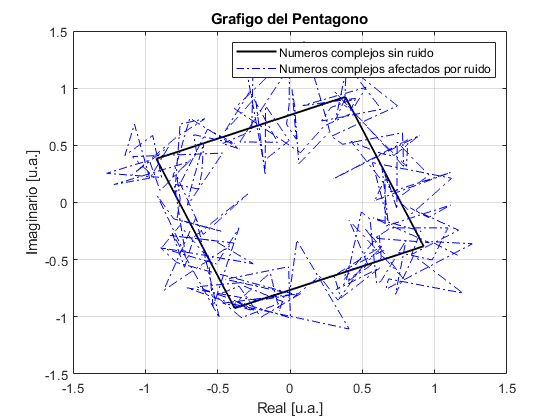

% Grafica de señal original y señal con ruido
f_plot_in_plane([Zpol3, Zpol3_r],leg,colors, "Grafigo del Pentagono")

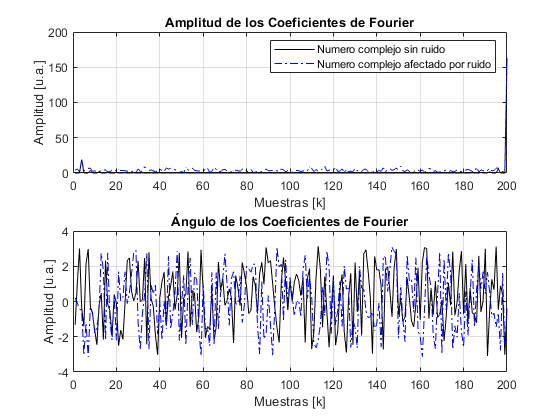

% Grafica de magnitud y angulo de frecuencias
Zpol3_w = fft(Zpol3);
Zpol3_w_r = fft(Zpol3_r);
f_plot_ang_phase(Zpol3_w, Zpol3_w_r);

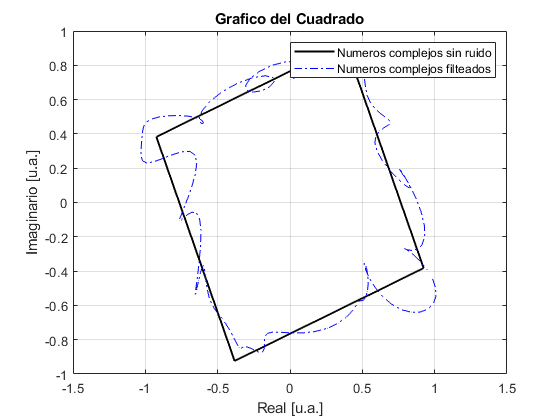

% Eliminacion de frecuencias altas
mitad = round(length(Zpol3)/2);
N = 80; % indices para quitar antes y despues de la mitad centrado en la mitad
zero_sample_idx = [mitad - N:mitad+N+1]; % debe ser simetrico con respecto a mitad
if zero_sample_idx(1) <= 0 | zero_sample_idx(end) > length(Zpol3)
    disp("ERROR: extremos de arreglo de indices que se quitan son suyperiores a limite ")
end
Zpol3_w_r_rem = Zpol3_w_r;
Zpol3_w_r_rem(zero_sample_idx) = 0;

% Reconstruccion de señal
Zpol3_rec = ifft(Zpol3_w_r_rem);

% Graficas de señal reconstruida
leg_rec = ["Numeros complejos sin ruido","Numeros complejos filteados"];
colors = ["k","b"];

f_plot_in_plane([Zpol3, Zpol3_rec],leg_rec,colors, "Grafico del Cuadrado") % en plano complejo

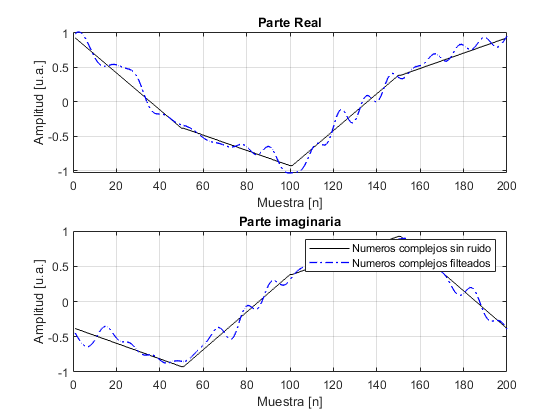

f_real_imag_plots(Zpol3,Zpol3_rec,leg_rec) % parte real e imaginaria

## **FUNCIONES AUXILIARES**

function Z = f_corazon()
% Calcula los puntos en el plano complejo correspondientes a un corazon
X_top = [linspace(-2,2,100)]';
Y_top = sqrt(1-(abs(X_top)-1).^2);
Z_top = X_top + 1j*Y_top;

X_down_right = [linspace(2,0,50)]';
Y_down_right = acos(1-X_down_right) - pi;
Z_down_right = X_down_right+ 1j*Y_down_right;

X_down_left = [linspace(0,-2,50)]';
Y_down_left= acos(1-abs(X_down_left)) - pi;
Z_down_left = X_down_left + 1j*Y_down_left;
% 
Z = [Z_top;Z_down_right;Z_down_left]; 
end

function Z = f_poligono(n)
% Dibuja un poligono centrado en (0,0) con n aristas
z_0 = 1j;
r = abs(z_0);
theta = angle(z_0);
k = [0:n];
z_n = (r^(1/n))*exp(1j*(theta + 2*k*pi)/n);
% Z = z_n
Z = []; % 50 puntos por arista del poligono
for i = 1:n
    j = i+1;
    if j > n
        j = 1;
    end
    x1 = real(z_n(i));
    y1 = imag(z_n(i));
    x2 = real(z_n(j));
    y2 = imag(z_n(j));
    z = [linspace(x1,x2,50) + 1j*linspace(y1,y2,50)]';
    Z = [Z;z];
end
end

function Z = f_estrella()
theta_0 = pi/2;
z = 1j;
X = [];
Y = [];
for i = 1:5
    theta_new = theta_0 + mod((i*4*pi)/5,2*pi);
    Z_new = exp(1j*(theta_new));
    X = [X;[linspace(real(z), real(Z_new), 20)]'];
    Y = [Y;[linspace(imag(z), imag(Z_new), 20)]'];
    z = Z_new;
end
Z = X + 1j*Y;
end

%--------------------------------------------------------------------------
% Para hacer graficas
function f_real_imag_plots(Z,Z2,leg)
% Grafica la parte real y la parte imaginaria de la señal original y de una
% segunda señal
% Z: señal numeros complejos sin ruido
% Z2: 2da señal de numeros complejos
% leg: leyenda de plots
figure;
subplot(2,1,1);
plot(real(Z),"k");
hold on;
plot(real(Z2),"-.b","LineWidth",1);
xlabel("Muestra [n]");
ylabel("Amplitud [u.a.]");
title("Parte Real");
grid on;

subplot(2,1,2);
plot(imag(Z),"k");
xlabel("Muestra [n]");
ylabel("Amplitud [u.a.]");
hold on;
plot(imag(Z2),"-.b","LineWidth",1);
title("Parte imaginaria");
legend(leg);
grid on;
end

function Zr = f_add_noise(Z,sd)
% Añade ruido con una desviacion estandar especificada
rX = normrnd(0,sd,[length(Z),1]); %ruido para parte real
rY = normrnd(0,sd,[length(Z),1]); % ruido para la parte imaginaria
Xr = real(Z)+rX;
Yr = imag(Z)+rY;
Zr = Xr + 1j*Yr;
end

function f_plot_in_plane(Z_mat,leg,colors,titulo)
% Grafica señal original y otras señales en el plano complejo
% La primera columna de Z_mat es la señal sin ruido
% Z_mat: matriz de numeros complejos, cada columna es una señal
% leg: leyenda
% colors: arreglo de colores
figure,
plot(Z_mat(:,1),'k',"LineWidth",1.5);
hold on;
grid on;
for i=2:size(Z_mat,2)
    plot(Z_mat(:,i),"-."+colors{i});
    hold on;
end
xlabel("Real [u.a.]");
ylabel("Imaginario [u.a.]");
title(titulo);
legend(leg);
end

function f_plot_ang_phase(Zw, Zw_r)
% Grafica amplitud y angulo de los coeficientes de la señal original y de la señal con ruido
% Zw: arreglo con muestras de frecuencias de señal sin ruido
% Zw_r: arreglo con muestras de frecuencias de señal con ruido
figure,
subplot(2,1,1);
plot(abs(Zw),'k');
grid on;
hold on;
plot(abs(Zw_r),"-.b");
xlabel("Muestras [k]");
ylabel("Amplitud [u.a.]")
title("Amplitud de los Coeficientes de Fourier");
legend("Numero complejo sin ruido","Numero complejo afectado por ruido");

subplot(2,1,2);
plot(angle(Zw),'k');
xlabel("Muestras [k]");
ylabel("Amplitud [u.a.]")
grid on;
hold on;
plot(angle(Zw_r),"-.b");
title("Ángulo de los Coeficientes de Fourier")
end